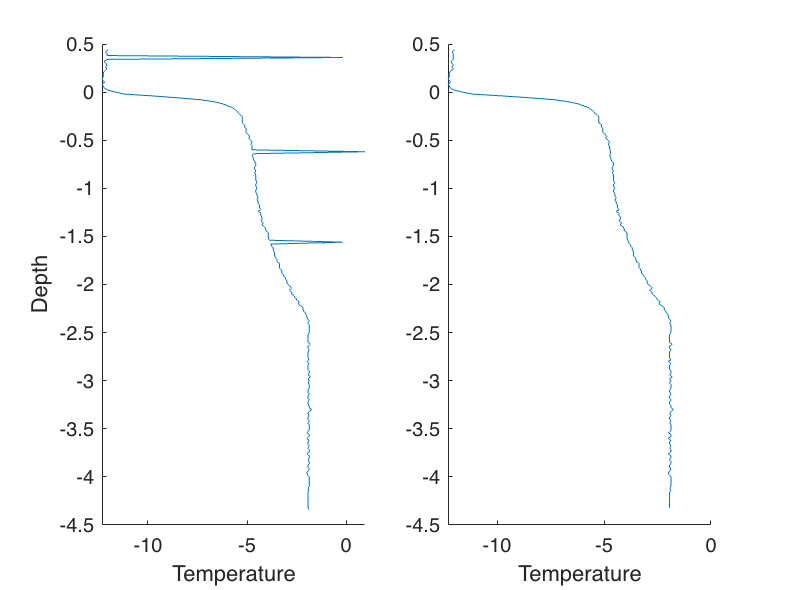

% DATA CLEANER
load data.mat

% data preview
figure; hold on;
subplot(1, 2, 1); hold on;
plot(temperature, depth);
ylabel 'Depth'
xlabel 'Temperature'

% dataset cleaner
% define the deltaT air -> sea
T_start = mean(temperature(1:10));
T_end = mean(temperature(end-10:end));
deltaT = abs(T_start - T_end);
% define a maximum delta between T[i] and T[i+1] 
% as a fraction of deltaT
wall = deltaT*0.20;

% filter
dT = diff(temperature);
valid_data = ~(abs(dT) > wall);
% remove points with dT greater then the wall
T = temperature(valid_data);
h = depth(valid_data);

% filtered data preview
subplot(1, 2, 2); hold on;
plot(T, h);

xlabel 'Temperature'

% ---------------------------------
% TOP-DOWN
% Second consecutive point out of control
% ---------------------------------

w = 10;   % moving window size
k = 3;    % factor

n = length(T);
out_of_control = 0;
flagged_idx = [];

% SCAN TOP-DOWN
for i = w:n
    mu = mean(T(1:i-3));
    sigma = std(T(1:i-3));
    UCL = mu + k*sigma;
    LCL = mu - k*sigma;

    if T(i) > UCL || T(i) < LCL
        out_of_control = out_of_control + 1;
    else
       out_of_control = 0; % reset counter if not consecutive
    end
    if out_of_control == 2
        flagged_idx = i;
        disp(flagged_idx);
        break;
    end
end

    22



% ----------------------------------------------
% CONTROL CHART - BOTTOM-UP
% Second consecutive point out of control
% ----------------------------------------------

w = 10;   % moving window size
k = 3;    % factor

n = length(T);
out_of_control = 0;
flagged_idx_bottomup = [];

% Scan BOTTOM-UP
for i = n-w+1:-1:1
    mu = mean(T(i+3:n));
    sigma = std(T(i+3:n));
    UCL = mu + k*sigma;
    LCL = mu - k*sigma;

    if T(i) > UCL || T(i) < LCL
        out_of_control = out_of_control + 1;
    else
        out_of_control = 0; % reset counter if not consecutive
    end

    if out_of_control == 2
        flagged_idx_bottomup = i;
        disp(flagged_idx_bottomup);
        break;
    end
end

   131



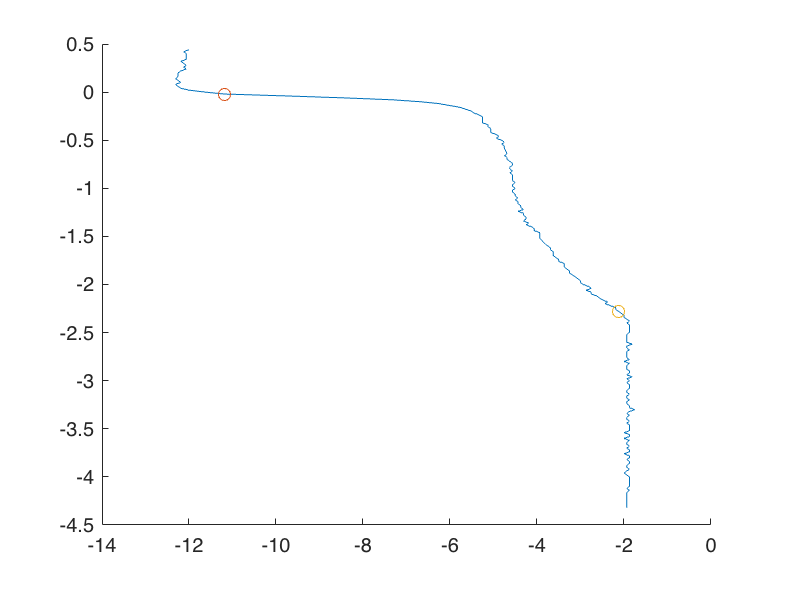

figure; hold on;
plot(T, h);
scatter(T(flagged_idx), h(flagged_idx));
scatter(T(flagged_idx_bottomup), h(flagged_idx_bottomup));

PA = [T(flagged_idx), h(flagged_idx)];
PC = [T(flagged_idx_bottomup), h(flagged_idx_bottomup)];

% ----------------------------------------------
% ISOLATE DATA BETWEEN PA and PC
% ----------------------------------------------

% PA and PC indices
idxA = flagged_idx;
idxC = flagged_idx_bottomup;

% Make sure idxA < idxC
if idxA > idxC
    temp = idxA;
    idxA = idxC;
    idxC = temp;
end

% Subset
P_T = T(idxA:idxC);
P_h = h(idxA:idxC);
nP = length(P_T);

% ----------------------------------------------
% LOOP OVER PX AND FIT SEGMENTS
% ----------------------------------------------

% Initialize arrays
slopes1 = zeros(nP-2, 1);
slopes2 = zeros(nP-2, 1);
rmse1   = zeros(nP-2, 1);
rmse2   = zeros(nP-2, 1);
rmse_mean = zeros(nP-2, 1);

% Loop over possible PX (exclude PA and PC)
for j = 2:nP-1

    % Segment 1: PA to PX
    X1 = P_T(1:j);
    Y1 = P_h(1:j);
    p1 = polyfit(X1, Y1, 1);
    Y1_fit = polyval(p1, X1);

    slopes1(j-1) = p1(1);
    rmse1(j-1) = sqrt(mean((Y1 - Y1_fit).^2));

    % Segment 2: PX to PC
    X2 = P_T(j:end);
    Y2 = P_h(j:end);
    p2 = polyfit(X2, Y2, 1);
    Y2_fit = polyval(p2, X2);

    slopes2(j-1) = p2(1);
    rmse2(j-1) = sqrt(mean((Y2 - Y2_fit).^2));

    % Mean error
    rmse_mean(j-1) = mean([rmse1(j-1), rmse2(j-1)]);
end

% ----------------------------------------------
% OUTPUT TABLE
% ----------------------------------------------

Results = table((idxA+1:idxC-1)', slopes1, slopes2, rmse1, rmse2, rmse_mean, ...
    'VariableNames', {'PX_idx','Slope1','Slope2','RMSE1','RMSE2','RMSE_Mean'});

disp(Results);

    PX_idx     Slope1       Slope2       RMSE1         RMSE2       RMSE_Mean
    ______    _________    ________    __________    __________    _________

      23      -0.013913    -0.50059    2.7428e-17       0.28669     0.14335 
      24      -0.014535     -0.5738     0.0004284       0.22888     0.11466 
      25      -0.015414    -0.62707     0.0012108       0.18447    0.092838 
      26      -0.017159    -0.65582     0.0038703       0.16304    0.083457 
      27      -0.019197    -0.67235      0.006843       0.15331    0.080075 
      28      -0.021466    -0.68113      0.010434       0.15011    0.080272 
      29      -0.023816    -0.68625      0.013955       0.14928    0.081618 
      30      -0.026269    -0.68785      0.017909       0.14982    0.083866 
      31      -0.028787  

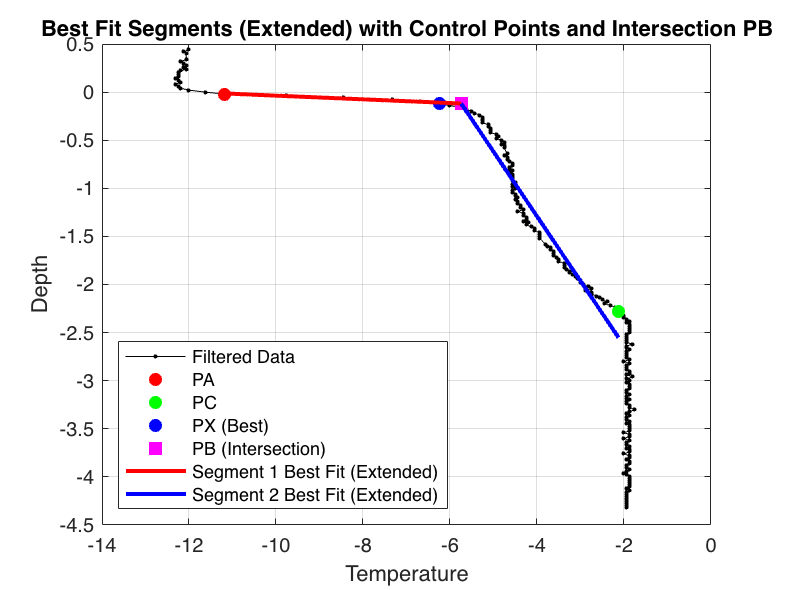

% ----------------------------------------------
% Plot original data and points PA, PX, PC, PB
% ----------------------------------------------

figure; hold on; grid on; box on;

% Data (T,h)
plot(T, h, 'k.-', 'DisplayName', 'Filtered Data');

% PA
plot(PA(1), PA(2), 'ro', 'MarkerFaceColor', 'r', 'DisplayName', 'PA');

% PC
plot(PC(1), PC(2), 'go', 'MarkerFaceColor', 'g', 'DisplayName', 'PC');

% PX
[~, best_idx] = min(Results.RMSE_Mean);
PX_idx = Results.PX_idx(best_idx);
PX = [T(PX_idx), h(PX_idx)];
plot(PX(1), PX(2), 'bo', 'MarkerFaceColor', 'b', 'DisplayName', 'PX (Best)');

% ----------------------------------------------
% Compute fits
% ----------------------------------------------

% Segment 1: PA to PX
X1 = T(idxA:PX_idx);
Y1 = h(idxA:PX_idx);
p1 = polyfit(X1, Y1, 1);

% Segment 2: PX to PC
X2 = T(PX_idx:idxC);
Y2 = h(PX_idx:idxC);
p2 = polyfit(X2, Y2, 1);

% ----------------------------------------------
% Compute PB (intersection)
% ----------------------------------------------

m1 = p1(1); q1 = p1(2);
m2 = p2(1); q2 = p2(2);

xPB = (q2 - q1) / (m1 - m2);
yPB = m1 * xPB + q1;
PB = [xPB, yPB];
plot(PB(1), PB(2), 'ms', 'MarkerSize', 8, 'MarkerFaceColor', 'm', 'DisplayName', 'PB (Intersection)');

% ----------------------------------------------
% Draw extended lines
% ----------------------------------------------

% For visual clarity, extend beyond PA/PX and PX/PC

% Line 1: from PA to PB
x1_ext = linspace(PA(1), PB(1), 100);
y1_ext = polyval(p1, x1_ext);
plot(x1_ext, y1_ext, 'r-', 'LineWidth', 2, 'DisplayName', 'Segment 1 Best Fit (Extended)');

% Line 2: from PB to PC
x2_ext = linspace(PB(1), PC(1), 100);
y2_ext = polyval(p2, x2_ext);
plot(x2_ext, y2_ext, 'b-', 'LineWidth', 2, 'DisplayName', 'Segment 2 Best Fit (Extended)');

% ----------------------------------------------
% Final touches
% ----------------------------------------------
xlabel('Temperature');
ylabel('Depth');
legend('show', 'Location', 'southwest');title('Best Fit Segments (Extended) with Control Points and Intersection PB');